pout = imread("pout.tif");
pout_imadjust = imadjust(pout);
pout_histeq = histeq(pout);
pout_adapthisteq = adapthisteq(pout);

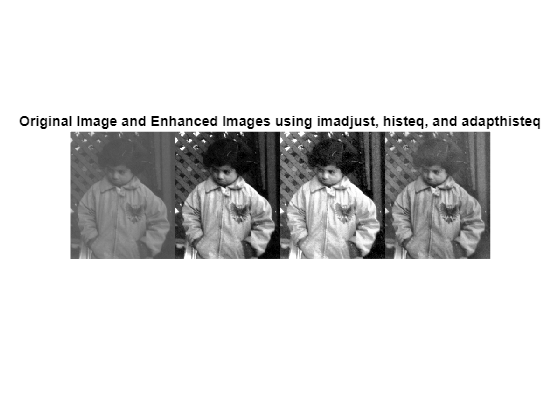

montage({pout,pout_imadjust,pout_histeq,pout_adapthisteq},"Size",[1 4])
title("Original Image and Enhanced Images using imadjust, histeq, and adapthisteq")

tire = imread("tire.tif");
tire_imadjust = imadjust(tire);
tire_histeq = histeq(tire);
tire_adapthisteq = adapthisteq(tire);

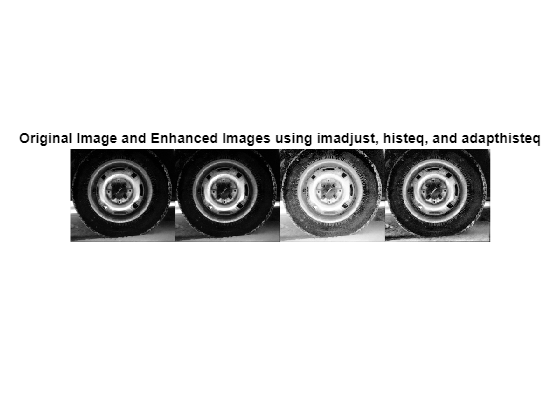

montage({tire,tire_imadjust,tire_histeq,tire_adapthisteq},"Size",[1 4])
title("Original Image and Enhanced Images using " + ...
    "imadjust, histeq, and adapthisteq")

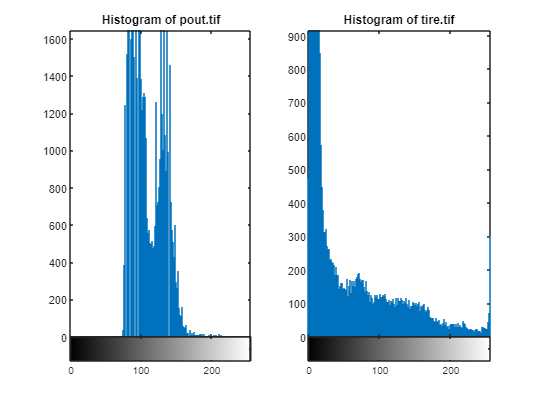

figure
subplot(1,2,1)
imhist(pout)
title("Histogram of pout.tif")
subplot(1,2,2)
imhist(tire)
title("Histogram of tire.tif");

shadow = imread("lowlight_1.jpg");
shadow_lab = rgb2lab(shadow);

max_luminosity = 100;
L = shadow_lab(:,:,1)/max_luminosity;

shadow_imadjust = shadow_lab;
shadow_imadjust(:,:,1) = imadjust(L)*max_luminosity;
shadow_imadjust = lab2rgb(shadow_imadjust);

shadow_histeq = shadow_lab;
shadow_histeq(:,:,1) = histeq(L)*max_luminosity;
shadow_histeq = lab2rgb(shadow_histeq);

shadow_adapthisteq = shadow_lab;
shadow_adapthisteq(:,:,1) = adapthisteq(L)*max_luminosity;
shadow_adapthisteq = lab2rgb(shadow_adapthisteq);

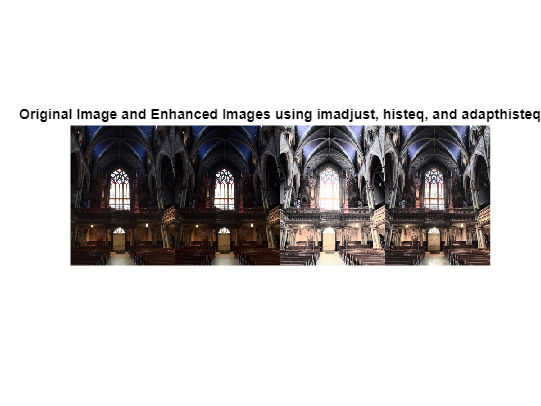

figure
montage({shadow,shadow_imadjust,shadow_histeq,shadow_adapthisteq},"Size",[1 4])
title("Original Image and Enhanced Images using " + ...
    "imadjust, histeq, and adapthisteq")